# Synthetic Aperture Radar Uncertainty Formation

This project aims to study Synthetic Aperture Radar (SAR) systems and to understand how uncertainties in timing and positioning will affect the resulting data in a SAR system. SAR systems use microwaves emitted from a moving platform at multiple locations to accurately observe distances, floral densities, soil moisture, and more. This project will focus on the simplistic case of using a satellite in Low Earth Orbit (LEO) to observe a simulated terrain as a way to understand how error will affect data. These findings should be able to be extrapolated to various other SAR applications, helping guide uncertainty quantities in suboptimal SAR systems and environments.

Script follows Simulated Land Scenes for Synthetic Aperture Radar Image Formation by Mathworks

Authors:

Robert King

Tejas Vinod

## Initialization

clear
clc

addpath("Helper Functions\") % Mathworks SAR Helper Functions
addpath("Terrain\") % Loads createTerrain Function and Terrain data files.

## Generate Simulated Terrain

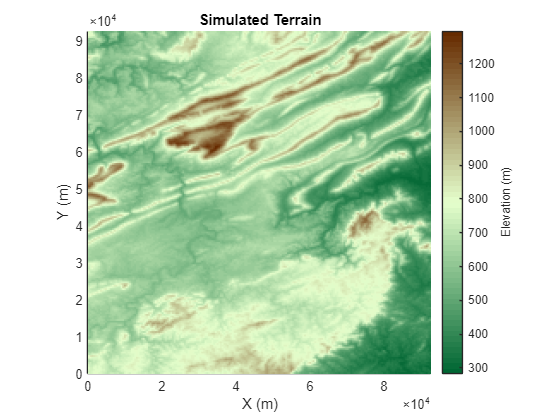

[xvec,yvec,A,xLimits,yLimits,resMapX,resMapY] = createTerrain(4);

% Plot simulated terrain
helperPlotSimulatedTerrain(xvec,yvec,A)
view([0 90])

## Specify the SAR System and Scenario

Define an C-band SAR imaging system to represent the Sentinel-1's imaging system. Range Resolution should be approximately 5 meters.

Data from: https://sentiwiki.copernicus.eu/web/s1-mission

% Define key radar parameters
freq = 5.405e9;                    % Carrier frequency (Hz)
[lambda,c] = freq2wavelen(freq);   % Wavelength (m) 
bw = 30e6;                         % Signal bandwidth, 0-100 MHz programmable (Hz)
fs = 60e6;                         % Sampling frequency, real sampling (Hz)
tpd = 3e-6;                        % Pulse width, 5-100 µs programmable (sec) 

% Verify that the range resolution is as expected
rngRes = bw2rangeres(bw)

rngRes = 4.9965

Specify the antenna aperture as 12.3 meters. Set the squint angle to 0 degrees for broadside operation. 

% Antenna properties
apertureLength = 12.3;              % Aperture length (m) 
sqa = 0;                            % Squint angle (deg)

Set the platform velocity to Sentinel-1's orbital vellocity and configure the platform geometry. The synthetic aperture length is 100 m as calculated by `sarlen`. 

% Platform properties

% Using Sentinel-1 as a reference orbit
% Constants
mu_E = 3.986004418e5;              % Earth gravitational parameter (km^3/s^2)
r_E = 6378.173;                    % Earth Equatorial Radius (km)

% Sentinel-1
alt_km = 700;                      % Altitude of Sentinel-1 (km)

r_orb = alt_km + r_E;              % Orbital Radius (km)
v_plat_kms = sqrt(mu_E/r_orb);     % Orbital Velocity (km/s)
v_gt_kms = r_E/r_orb * v_plat_kms; % Ground Track Velocity (km/s)

% Original Variables
rdrhgt = alt_km*1e3;               % Height of platform (m) 
v_plat = v_plat_kms*1e3;           % Speed of the platform (m/s) 

dist = diff(xLimits);              % Ground Track Distance to be Observed (km)
dur = dist*1e-3/v_gt_kms;               % Duration of flight (s) 

rdrpos1 = [0 0 rdrhgt];            % Start position of the radar (m)
rdrvel = [0 v_plat 0];             % Radar plaform velocity
rdrpos2 = rdrvel*dur + rdrpos1;    % End position of the radar (m)

len = sarlen(rdrhgt,lambda,apertureLength) % Synthetic aperture length (m)

len = 3.1566e+03

Define the targets. The targets in this example are stationary and are intended to represent calibration targets. Set the target heights to 110 meters, relative to the surface. This height was selected such that targets may be occluded due to the hilly terrain. 

% Configure the target platforms in x and y
targetpos = [xvec(floor(0.25*length(xvec))),yvec(floor(0.5*length(yvec))),0;xvec(floor(0.5*length(xvec))),yvec(floor(0.5*length(yvec))),0;xvec(floor(0.75*length(xvec))),yvec(floor(0.5*length(yvec))),0]; % Target positions (m)
tgthgts = 1*ones(1,3); % Target height (m)
for it = 1:3 
    % Set target height relative to terrain
    [~,idxX] = min(abs(targetpos(it,1) - xvec)); 
    [~,idxY] = min(abs(targetpos(it,2) - yvec)); 
    tgthgts(it) = tgthgts(it) + A(idxX,idxY); 
    targetpos(it,3) = tgthgts(it); 
end

Next, set the reference slant range, which is used in subsequent processing steps such as determining appropriate pointing angles for the radar antenna. Calculate the cross-range resolutions using the `sarazres` function. Based on the geometry and radar settings, the cross-range resolution is about 2 meters. 

% Set the reference slant range for the cross-range processing
rc = sqrt((rdrhgt - mean(tgthgts))^2 + (mean(targetpos(:,1)))^2);

% Antenna orientation
depang = depressionang(rdrhgt,rc,'Flat','TargetHeight',mean(tgthgts)); % Depression angle (deg)
grazang = depang; % Grazing angle (deg)

% Azimuth resolution
azResolution = sarazres(rc,lambda,len)  % Cross-range resolution (m)

azResolution = 6.1575

Then, determine an appropriate pulse repetition frequency (PRF) for the SAR system. In a SAR system, the PRF has dual implications. The PRF not only determines the maximum unambiguous range but also serves as the sampling frequency in the cross-range direction. If the PRF is too low, the pulses are long in duration, resulting in fewer pulses illuminating a particular region. If the PRF is too high, the cross-range sampling is achieved but at the cost of reduced maximum range. The `sarprfbounds` function suggests maximum and minimum PRF bounds. 

% Determine PRF bounds 
[swlen,swwidth] = aperture2swath(rc,lambda,apertureLength,grazang);
[prfmin,prfmax] = sarprfbounds(v_plat,azResolution,swlen,grazang,"PulseWidth",tpd)

prfmin = 1.2187e+03

prfmax = 2.2808e+05

For this example, set the PRF to 2000 Hz. 

% Select a PRF within the PRF bounds
prf = 2000; % Pulse repetition frequency (Hz)

Now that the parameters for the radar and targets are defined. Set up a radar scene using `radarScenario`. Add the radar platform and targets to the scene with `platform`. Set the target radar cross section (RCS) to 5 dBsm, and plot the scene. 

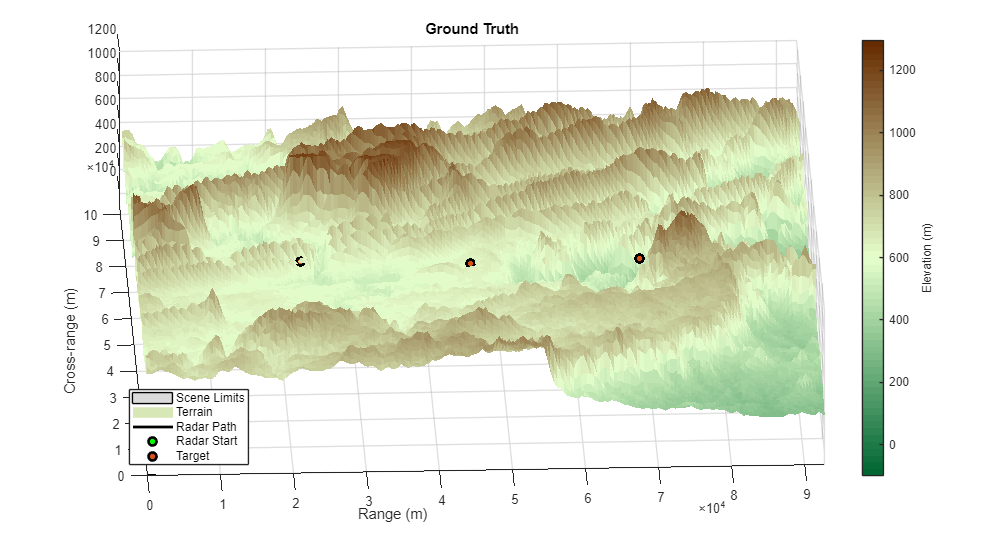

% Create a radar scenario
scene = radarScenario('UpdateRate',prf,'IsEarthCentered',false,'StopTime',dur);

% Add platforms to the scene using the configurations previously defined 
rdrplat = platform(scene,'Trajectory',kinematicTrajectory('Position',rdrpos1,'Velocity',[0 v_plat 0]));

% Add target platforms
rcs = rcsSignature('Pattern',5); 
for it = 1:3
    platform(scene,'Position',targetpos(it,:),'Signatures',{rcs});
end

% Plot ground truth
helperPlotGroundTruth(xvec,yvec,A,rdrpos1,rdrpos2,targetpos)

Note that the terrain generated has been limited in range and cross-range to the expected beam location. This is to conserve memory, as well as to speed up the simulation. 

## Define the Land Surface Reflectivity

Now that the radar scenario and its platforms are set, define the land surface. First, select a reflectivity model. Radar Toolbox™ offers 7 different reflectivity models covering a wide range of frequencies, grazing angles, and land types. The asterisk denotes the default model. Type `help` `landreflectivity` or `doc` `landreflectivity` in the Command Window for more information on usage and applicable grazing angles for each model. The land reflectivity models are as follows. 

- **APL:** Mathematical model supporting low to high grazing angles over frequencies in the range from 1 to 100 GHz. Land types supported are urban, high-relief, and low-relief. 

- **Barton*: **Mathematical model supporting medium grazing angles over frequencies in the range from 1 to 10 GHz. Land types supported are rugged mountains, mountains, metropolitan, urban, wooded hills, rolling hills, woods, farm, desert, flatland, and smooth. This is the default model. 

- **Billingsley:** Empirical model valid for low grazing angles over frequencies from 3 MHz to 12 GHz. Land types supported are low-relief rural, low-relief forest, farm, desert, marsh, grassland, high-relief rural, high-relief forest, mountains, urban, low-relief urban. 

- **GIT: **Semi-empirical model for medium grazing angles over frequencies in the range from 3 to 15 GHz. Land types supported are soil, grass, tall grass, trees, and urban. 

- **Morchin:** Mathematical model for high grazing angles over frequencies in the range from 300 MHz to 8 GHz. Land types supported are desert, farm, woods, and mountains. 

- **Nathanson:** Empirical model for low to medium grazing angles over frequencies in the range from 1 to 36 GHz. Land types supported are desert, farm, woods, jungle, rolling hills, and urban. 

- **Ulaby-Dobson:** Semi-empirical model for low to medium grazing angles over frequencies in the range from 1 to 18 GHz. Land types supported are soil, grass, shrubs, and short vegetation. 

For this example, use the default Barton model, since it has such a large number of land types. For terrain values above 100 meters, assign reflectivity values for wooded hills. Otherwise, set reflectivity values to woods. Plot the reflectivity map to see the assignments

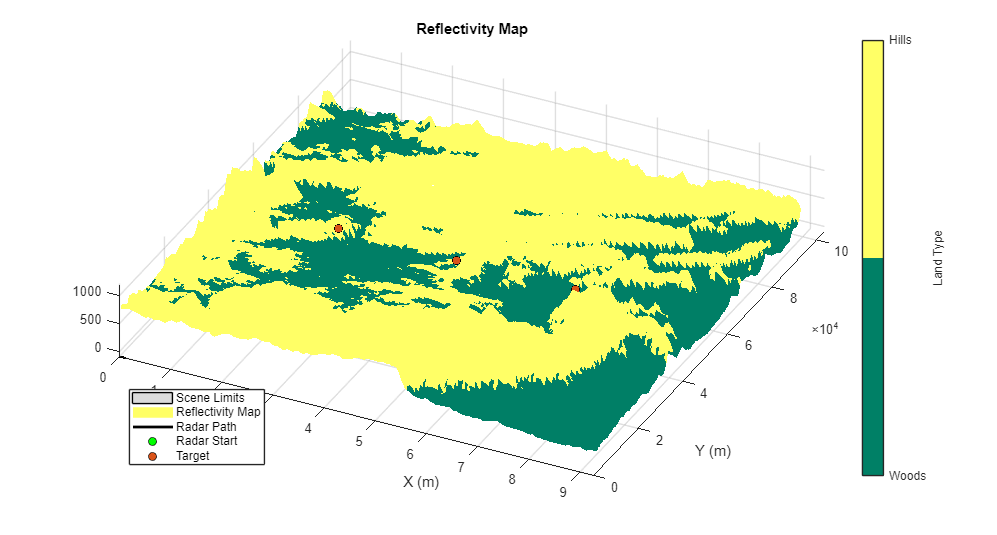

% Specify custom reflectivity map
grazTable = 20:0.1:60;
freqTable = [1e9 10e9]; 
numSurfaces = 2;
reflectivityLayers = zeros(numel(grazTable),numel(freqTable),numSurfaces);
reflectivityLayers(:,:,1) = landreflectivity('Woods', ...
    grazTable,freqTable);
reflectivityLayers(:,:,2) = landreflectivity('WoodedHills', ...
    grazTable,freqTable);
reflectivityType = ones(size(A)); 
reflectivityType(A > 620) = 2; 

% Plot custom reflectivity map
helperPlotReflectivityMap(xvec,yvec,A,reflectivityType,rdrpos1,rdrpos2,targetpos)

Next, compose the custom reflectivity map for use by radarScenario using `surfaceReflectivity`. Set the `Speckle` property to `Rayleigh`. The `surfaceReflectivity` objects model speckle as an uncorrelated multiplicative factor as 

$I=\sigma \cdot n$,

where $\sigma$ is the surface reflectivity and $n$ is an independent and identically distributed (IID) random value that is often defined as having unity mean noise. Common speckle models include Weibull, Rayleigh, and lognormal, which are all options provided by `surfaceReflectivity`. You can tailor the speckle with the distribution's corresponding properties. For a Rayleigh distribution, you can modify the `SpeckleScale` property. 

reflectivityMap = surfaceReflectivity('Custom','Frequency',freqTable, ...
    'GrazingAngle',grazTable,'Reflectivity',reflectivityLayers, ...
    'Speckle','Rayleigh')

reflectivityMap =   surfaceReflectivityCustom with properties:

    EnablePolarization: 0
          Reflectivity: [401×2×2 double]
             Frequency: [1.0000e+09 1.0000e+10]
          GrazingAngle: [20 20.1000 20.2000 20.3000 20.4000 20.5000 20.6000 20.7000 20.8000 20.9000 21 21.1000 21.2000 21.3000 21.4000 21.5000 21.6000 21.7000 21.8000 21.9000 22 22.1000 22.2000 22.3000 22.4000 22.5000 22.6000 22.7000 … ] (1×401 double)
               Speckle: 'Rayleigh'
          SpeckleScale: 0.7979


Add a land surface to the radar scenario using `landSurface`. Assign the random height map previously generated and the reflectivity map to the land surface. 

% Add land surface to scene
s = landSurface(scene,'Terrain',A,'Boundary',[xLimits;yLimits], ...
    'RadarReflectivity',reflectivityMap, ...
    'ReflectivityMap',reflectivityType);

## Configure the Radar Transceiver

In this section, configure the radar system properties. Define the antenna and the transmitted linear frequency modulated (LFM) waveform. Assign the radar sensor to the radar platform. 

% Create a radar looking to the right
maxRange = 2500; % Maximum range for IQ collection
mountAngles = [0 depang 0];
rdr = radarTransceiver('MountingAngles',mountAngles,'NumRepetitions',1, ...
    'RangeLimits',[0 maxRange]);

% Set peak power
rdr.Transmitter.PeakPower = 4.2215e3; 

% Set receiver sample rate and noise figure
rdr.Receiver.SampleRate = fs;
rdr.Receiver.NoiseFigure = 30; 

% Define transmit and receive antenna and corresponding parameters
antbw = ap2beamwidth(apertureLength,lambda); 
ant = phased.SincAntennaElement('FrequencyRange',[5.355e9 5.455e9],'Beamwidth',antbw);
rdr.TransmitAntenna.Sensor = ant;
rdr.TransmitAntenna.OperatingFrequency = freq;
rdr.ReceiveAntenna.Sensor = ant;
rdr.ReceiveAntenna.OperatingFrequency = freq;
antennaGain = aperture2gain(apertureLength^2,lambda); 
rdr.Transmitter.Gain = antennaGain;
rdr.Receiver.Gain = antennaGain;

% Configure the LFM signal of the radar
rdr.Waveform = phased.LinearFMWaveform('SampleRate',fs,'PulseWidth',tpd, ...
    'PRF',prf,'SweepBandwidth',bw); 

% Add radar to radar platform
rdrplat.Sensors = rdr;

## Generate the Datacube

Now that the scene and the radar system are defined, generate returns from the land surface with the `clutterGenerator` method. By default, `clutterGenerator` will simulate clutter returns in the mainlobe. For more information about clutter modeling, see [Introduction to Radar Scenario Clutter Simulation](docid:radar_ug#example-ex26628691).

% Collect clutter returns with the clutterGenerator
clutterGenerator(scene,rdr,'Resolution',rngRes/2, ...
    'RangeLimit',maxRange);

% Initialize output IQ datacube
minSample = 500; % Minimum sample range
truncRngSamp = ceil(range2time(maxRange)*fs); % Limit the number of samples
T = 1/prf; % Pulse repetition interval (sec)
numPulses = round(dur/T + 1); % Number of pulses 
raw = zeros(numel(minSample:truncRngSamp),502); % IQ datacube 

Data is collected with the `receive` method. Either load in the data or simulate the raw SAR returns. If you choose to simulate the IQ, as the IQ data is received, a plot of the raw signal returns is generated. Otherwise, the unprocessed datacube is plotted at once. The raw signal is the collection of pulses transmitted in the cross-range direction. The plot shows the real part of the signal for the three targets and the land surface.

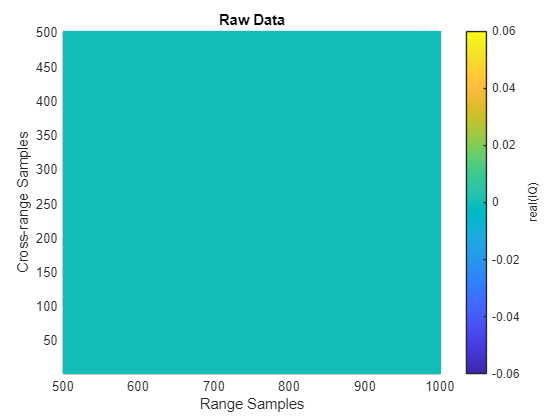

% Collect IQ 
ii = 1; 
hRaw = helperPlotRawIQ(raw,minSample);

simulateData = true; % Change to true to simulate IQ
if simulateData
    while advance(scene) %#ok<UNRCH>
        tmp = receive(scene); % nsamp x 1
        raw(:,ii) = tmp{1}(minSample:truncRngSamp);
        if mod(ii,1000) == 0 % Update plot after 100 pulses
            helperUpdatePlotRawIQ(hRaw,raw);
        end
        ii = ii + 1;
    end
else
    load('rawSAR.mat'); %#ok<UNRCH>
end
helperUpdatePlotRawIQ(hRaw,raw);

As is evident in the fully formed plot, the returns from the targets and the land surface are widely distributed in range and cross-range. Thus, it is difficult to distinguish the individual targets in the raw two-dimensional SAR data. The area where it is evident that returns are present is the mainlobe of the antenna. If you want to image a larger region, a couple of changes you can implement are: 

- Increase the altitude of the SAR imaging platform or 

- Increase the beamwidth. 

## Visualize SAR Data 

Focus the image using the range migration algorithm. The range-migration algorithm corrects for the range-azimuth coupling, as well as the azimuth-frequency dependence. The algorithm proceeds as:

- **FFT:** First, the algorithm performs a two-dimensional FFT. This transforms the SAR signal into wavenumber space. 

- **Matched Filtering:** Second, the algorithm focuses the image using a reference signal. This is a bulk focusing stage. The reference signal is computed for a selected range, often the mid-swath range. Targets at the selected range will be correctly focused, but targets away from the reference are only partially focused. 

- **Stolt Interpolation: **Next is a differential focusing stage that uses Stolt interpolation to focus the remainder of the targets. 

- **IFFT: **Finally, a two-dimensional IFFT is performed to return the data to the time domain.

Based on the radar waveform, use the `rangeMigrationLFM` function to form the single-look complex (SLC) image and plot the results. After range and cross-range processing, two targets can be distinguished from the background. 

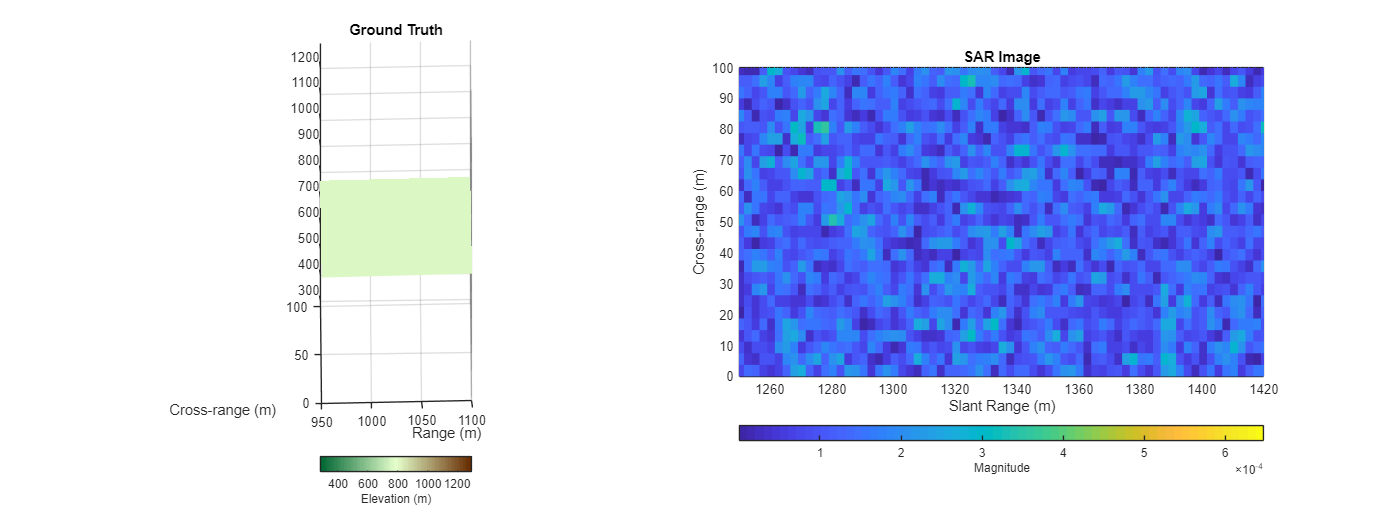

% Generating Single Look Complex image using range migration algorithm
slcimg = rangeMigrationLFM(raw,rdr.Waveform,freq,v_plat,rc);
helperPlotSLC(slcimg,minSample,fs,v_plat,prf,rdrpos1,targetpos, ...
    xvec,yvec,A)

## Verify Occultation Times

SAR images are similar to optical images, but the physics is quite different. Since SAR uses slant range to form images, higher elevation targets appear closer to the radar than lower elevation targets, resulting in higher elevation targets appearing at nearer ranges in the SAR image. This distortion is called layover and is noticeable in the image. Additionally, the actual grazing angles change slightly over the imaged swath, with shallower angles existing at farther ranges and steeper angles at closer ranges. These characteristics among others result in warped images in comparison to the Cartesian ground truth. 

The occlusion method helps us to further interpret the results. Using the `occlusion` method on the land surface, determine the visibility of the targets throughout the scenario. 

for it = 1:3
    % Determine whether the target was occluded
    occ = false(1,floor(numPulses)); 
    for ip = 1:floor(numPulses)
        rdrpos = rdrpos1 + rdrvel.*1/prf*(ip - 1); 
        occ(ip) = s.occlusion(rdrpos,targetpos(it,:));
    end

    % Translate occlusion values to a visibility status
    helperGetVisibilityStatus(it,occ)
end

Target 1 is fully visible during the scenario (visible 100% of the data collection).
Target 2 is fully visible during the scenario (visible 100% of the data collection).
Target 3 is fully visible during the scenario (visible 100% of the data collection).


The first target is not visible at all, because it is occluded by the terrain. The second target is only partially visible throughout the collection. This causes missing data in the cross-range dimension, which results in the increased sidelobes and decreased signal power. The third target is fully visible throughout the target collection. It is bright and focused. 

## Summary

This example demonstrated how to generate IQ from a stripmap-based SAR scenario with three targets over land terrain. This example showed you how to: 

- Configure the SAR radar parameters,

- Define the radar scenario,

- Build a custom reflectivity map, 

- Add terrain to the scene with added speckle, 

- Generate IQ, and 

- Form a focused SAR image.

This example can be easily modified for other platform geometries, radar parameters, and surface types. 